## Задание 1. Исследование LQR.

function observable(A, C)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function [P, K] = get_K_Ric(A, B, Q, R)
    syms P_ [3, 3]
    eqs = [A'*P_ + P_*A - P_*B*inv(R)*B'*P_ + Q == 0];
    s = vpasolve(eqs, [P_], 'Random', true);

    % Initialize K as empty in case no positive definite P is found
    K = [];
    
    % Iterate over the solutions
    for i = 1:length(s.P_1_1)
        P = [s.P_1_1(i) s.P_1_2(i) s.P_1_3(i);
             s.P_2_1(i) s.P_2_2(i) s.P_2_3(i);
             s.P_3_1(i) s.P_3_2(i) s.P_3_3(i)];
        
        % Check if P is positive definite
        if all(eig(P) > 0)
            K = -inv(R) * B' * double(P);
            P = double(P);
            break; % Stop after finding the first valid K
        end
    end
end
function simsys1(A, B, K, Q, R, x0, t_end, Jmin, idx)    
    % Define the closed-loop dynamics
    A_cl = A + B * K;
    
    % Time vector for simulation
    t_span = [0 t_end];
    
    % Solve the closed-loop system using ode45
    [t, x] = ode45(@(t, x) A_cl * x, t_span, x0);
    
    % Compute control input u(t)
    u = (K * x')';
    
    % Initialize Jexp(t)
    Jexp = zeros(size(t));
    
    % Compute Jexp(t) incrementally
    for i = 2:length(t)
        dt = t(i) - t(i-1);
        x_mid = (x(i, :)' + x(i-1, :)') / 2; % Midpoint approximation
        u_mid = (u(i, :)' + u(i-1, :)') / 2;
        Jexp(i) = Jexp(i-1) + (x_mid' * Q * x_mid + u_mid' * R * u_mid) * dt;
    end

    disp("Jexp");
    disp(Jexp(size(Jexp)));
    
    % Plot results
    figure('Position', [0 0 500 500]);
    
    m = 3;
    n = 1;

    % Plot control input
    subplot(m, n, 1);
    plot(t, u, 'LineWidth', 1.5);
    title('Control Input u(t)');
    xlabel('Time (s)');
    ylabel('u(t)');
    grid on;
    
    % Plot state trajectories
    subplot(m, n, 2);
    plot(t, x, 'LineWidth', 1.5);
    title('State Trajectories x(t)');
    xlabel('Time (s)');
    ylabel('x(t)');
    legend(arrayfun(@(i) sprintf('x_%d', i), 1:size(x, 2), 'UniformOutput', false), 'Location', 'eastoutside');
    grid on;
    
    % Plot Jexp(t) and compare with Jmin
    subplot(m, n, 3);
    plot(t, Jexp, 'LineWidth', 1.5);
    hold on;
    yline(Jmin, '--r', 'LineWidth', 1.5);
    title('Quality Functional J_{exp}(t)');
    xlabel('Time (s)');
    ylabel('J_{exp}(t)');
    legend('J_{exp}(t)', 'J_{min}', 'Location', 'eastoutside');
    grid on;
    
    % Save the figure
    exportgraphics(gcf, ['figs/1_sim' int2str(idx) '.png'], 'Resolution', 500);
end

% Define system matrices
A = [3 5 4; -2 -4 -5; 2 2 3]; % Replace with your matrix from Table 2
B = [2; -1; 1]; % Replace with your matrix from Table 2
x0 = [1; 1; 1];

% Define parameters
Q1 = eye(3);
R1 = 1;
alpha = 1000;

% Store Q and R matrices in cell arrays
Q_matrices = {Q1, alpha*Q1, Q1, alpha*Q1};
R_matrices = {R1, R1, alpha*R1, alpha*R1};

% Check observability
observable(Q1, A);

Ob =      3     5     4
    -2    -4    -5
     2     2     3
     3     5     4
    -2    -4    -5
     2     2     3
     3     5     4
    -2    -4    -5
     2     2     3


rank_Ob = 3

YES


observable(alpha*Q1, A);

Ob =            3           5           4
          -2          -4          -5
           2           2           3
        3000        5000        4000
       -2000       -4000       -5000
        2000        2000        3000
     3000000     5000000     4000000
    -2000000    -4000000    -5000000
     2000000     2000000     3000000


rank_Ob = 3

YES


For Q1 and R1:


P matrix:


    2.4117    2.0501   -1.1936
    2.0501    2.1782   -0.5442
   -1.1936   -0.5442    8.9601



K matrix:


   -1.5798   -1.3778   -7.1171



Jmin1: 14.1748


Jexp
   14.1845
         0



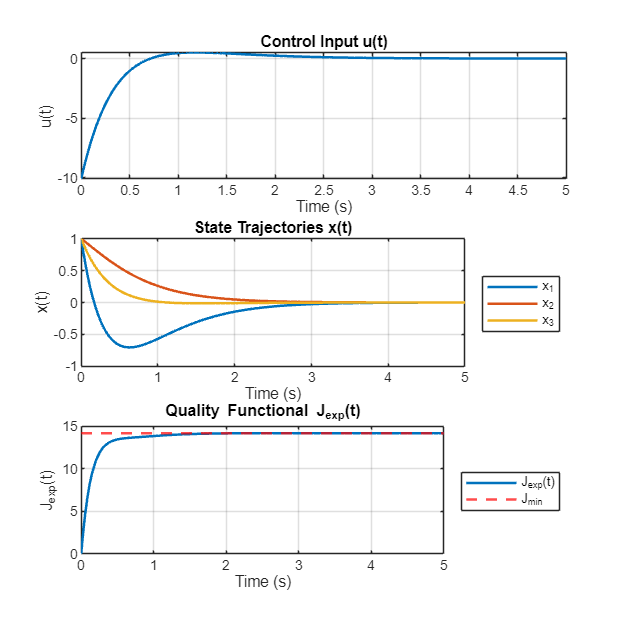

For Q2 and R2:


P matrix:


   1.0e+03 *

    0.4872    0.1268   -0.8512
    0.1268    0.2100   -0.0619
   -0.8512   -0.0619    1.7117



K matrix:


    3.4317   18.4307  -71.2742



Jmin2: 836.2982


Jexp
  836.3231
         0



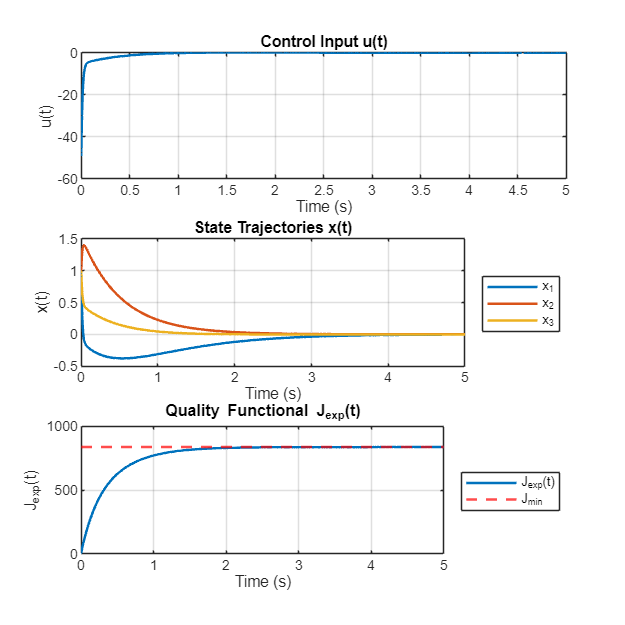

For Q3 and R3:


P matrix:


   1.0e+03 *

    1.9205    1.9201   -0.3209
    1.9201    1.9203   -0.3202
   -0.3209   -0.3202    6.7223



K matrix:


   -1.6000   -1.5997   -6.4008



Jmin3: 13121.0890


Jexp
   1.0e+04 *

    1.3133
         0



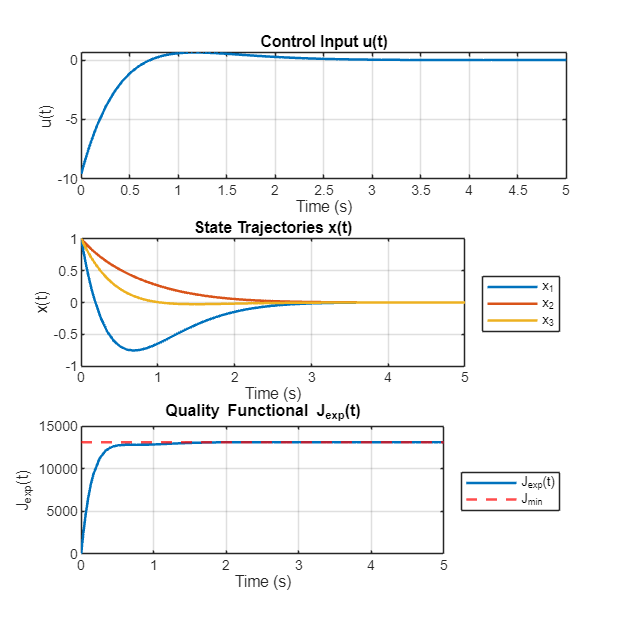

For Q4 and R4:


P matrix:


   1.0e+03 *

    2.4117    2.0501   -1.1936
    2.0501    2.1782   -0.5442
   -1.1936   -0.5442    8.9601



K matrix:


   -1.5798   -1.3778   -7.1171



Jmin4: 14174.7696


Jexp
   1.0e+04 *

    1.4184
         0



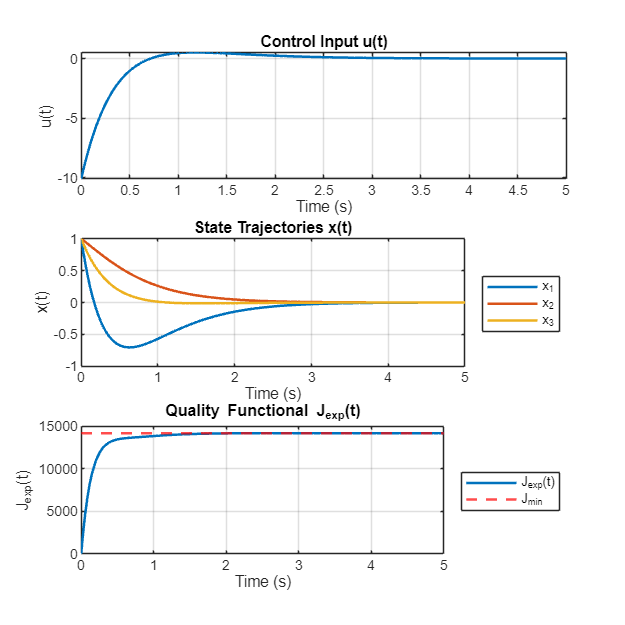


% Preallocate results
P = cell(1, 3);
K = cell(1, 4);
Jmin = zeros(1, 4);

% Loop through each set of Q and R matrices
for i = 1:4
    [P{i}, K{i}] = get_K_Ric(A, B, Q_matrices{i}, R_matrices{i});
    Jmin(i) = x0' * P{i} * x0;
end

% Display results
for i = 1:4
    fprintf('For Q%d and R%d:\n', i, i);
    disp('P matrix:');
    disp(P{i});
    disp('K matrix:');
    disp(K{i});
    fprintf('Jmin%d: %.4f\n', i, Jmin(i));
    simsys1(A, B, K{i}, Q_matrices{i}, R_matrices{i}, x0, 5, Jmin(i), i);
end

## Задание 2. Исследование фильтра Калмана.

function L = get_L_Ric(A, C, Q, R)
    nu = 1;
    [P1,~,K] = icare(A', C', Q, R, [], [], [], nu);    
    L = -P1* C' * inv(R);
end
function simsys2(A, C, L, x0, x0_hat, t_end, idx)
    % Time vector for simulation
    dt = 0.01; % Time step
    t = 0:dt:t_end;

    % Generate random inputs
    f = mvnrnd(zeros(1, 4), eye(4), length(t))'; % Gaussian noise for f(t)
    xi = mvnrnd(zeros(1, size(C, 1)), 1, length(t))'; % Gaussian noise for ξ(t)
    
    % Load the Simulink model (assuming it's named 'observer_model.slx')
    model_name = 'task2';
    load_system(model_name);
    
    % Set simulation parameters
    assignin('base', 'A', A);
    assignin('base', 'C', C);
    assignin('base', 'L', L);
    assignin('base', 'x0', x0);
    assignin('base', 'x0_hat', x0_hat);
    
    sim_out = sim(model_name, 'StopTime', num2str(t_end));

    % Extract outputs
    t_sim = sim_out.tout;
    x = squeeze(sim_out.yout{1}.Values.Data);
    x_hat = sim_out.yout{2}.Values.Data(:,:,1)';
    
    % Compute error
    e = x - x_hat;

    % Plot results (same as your original code)
    figure('Position', [0 0 700 700]);
    m = 3; % Number of rows
    n = 2; % Number of columns

    % Plot state trajectories x(t) and x_hat(t)
    for i = 1:length(x0)
        subplot(m, n, i);
        plot(t_sim, x(i, :), 'LineWidth', 1.5);
        hold on;
        plot(t_sim, x_hat(i, :), '--', 'LineWidth', 1.5);
        title(sprintf('State x_%d and Estimated hat x_%d', i, i));
        xlabel('Time (s)');
        ylabel(sprintf('x_%d, hat x_%d', i, i));
        legend(sprintf('x_%d', i), sprintf('hat x_%d', i), 'Location', 'eastoutside');
        grid on;
    end

    % Plot observer error e(t)
    subplot(m, n, [5,6]);
    plot(t_sim, e, 'LineWidth', 1.5);
    title('Observer Error e(t)');
    xlabel('Time (s)');
    ylabel('e(t)');
    legend({'e_1', 'e_2', 'e_3', 'e_4'}, 'Location', 'eastoutside');
    grid on;

    % Save the figure
    exportgraphics(gcf, ['figs/2_sim' int2str(idx) '.png'], 'Resolution', 500);
end

A = [
    25 8 -20 13
    -38 -11 30 -18
    40 13 -33 21
    38 12 -32 19
];
C = [7 2 -5 3];
x0 = [1; 1; 1; 1];
x0_hat = [0; 0; 0; 0]

x0_hat =      0
     0
     0
     0


observable(A, C);

Ob =      7     2    -5     3
    13     5   -11     7
   -39   -10    29   -19
  -157   -53   131   -79


rank_Ob = 4

YES


For Q1 and R1:


L matrix:


   -2.6323
  -12.9504
   -6.7362
   -0.4351



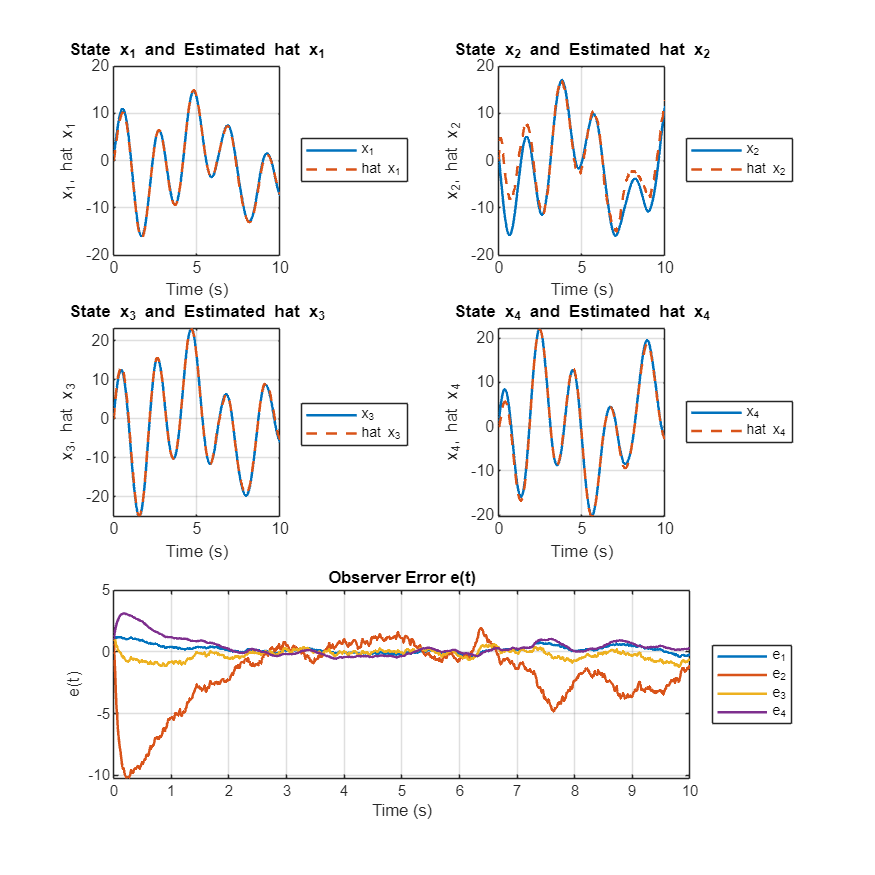

For Q2 and R2:


L matrix:


   20.0527
 -530.3858
  -49.4616
  124.9529



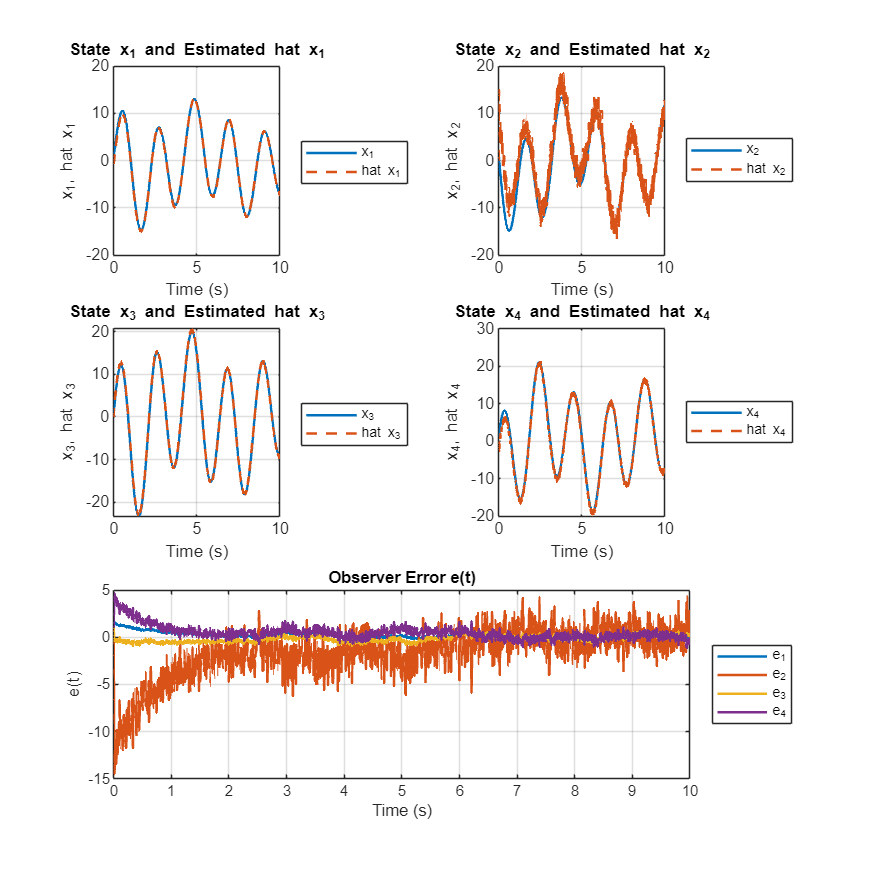

For Q3 and R3:


L matrix:


   -0.5258
    0.0379
   -0.8397
   -0.3869



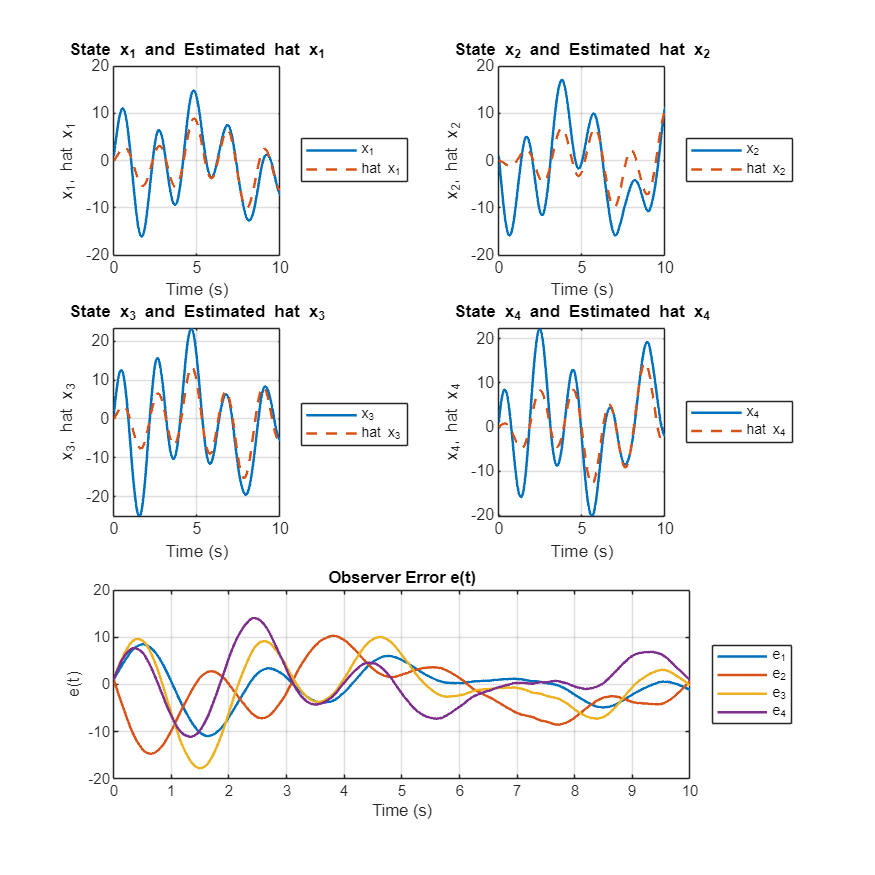

For Q4 and R4:


L matrix:


   -2.6323
  -12.9504
   -6.7362
   -0.4351



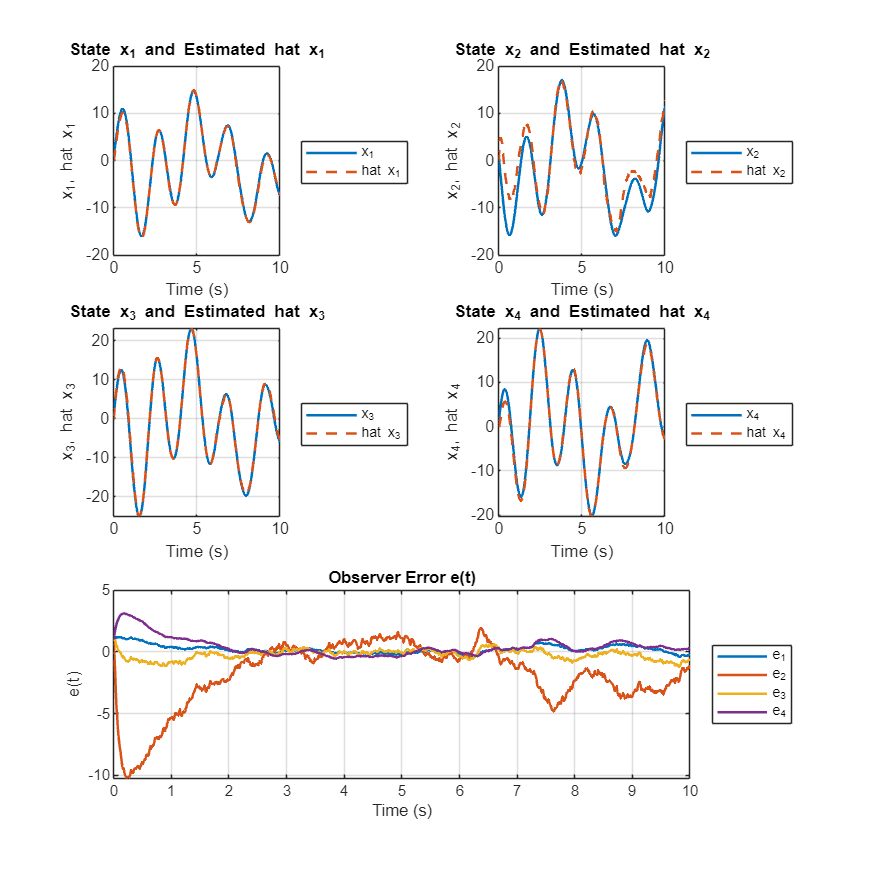

% Define parameters
Q1 = eye(4);
R1 = 1;
alpha = 1000;

% Store Q and R matrices in cell arrays
Q_matrices = {Q1, alpha*Q1, Q1, alpha*Q1};
R_matrices = {R1, R1, alpha*R1, alpha*R1};

% Preallocate results
P = cell(1, 4);
Ls = cell(1, 4);

% Loop through each set of Q and R matrices
for i = 1:4
    Ls{i} = get_L_Ric(A, C, Q_matrices{i}, R_matrices{i});
end

% Display results
for i = 1:4
    fprintf('For Q%d and R%d:\n', i, i);
    disp('L matrix:');
    disp(Ls{i});
    simsys2(A, C, Ls{i}, x0, x0_hat, 10, i);
end

## Задание 3. Синтез LQG.

function controllable(A, B)
    Co = ctrb(A, B)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function analyze_observabillity(A, C)
    eigenvalues = eig(A);
    observ_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A; C]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            observ_result = false;
            fprintf(' is not observable.\n');
        else
            fprintf(' is observable.\n');
        end
    end
    
    if observ_result
        disp('The system is fully observable.');
    else
        disp('The system is not fully observable.');
    end
end
function simsys3(A, B, C, D, K, L, x0, x0_hat, t_end)
    % Load the Simulink model (assuming it's named 'observer_model.slx')
    model_name = 'task3';
    load_system(model_name);
    
    % Set simulation parameters
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'D', D);
    assignin('base', 'C', C);
    assignin('base', 'K', K);
    assignin('base', 'L', L);
    assignin('base', 'x0', x0);
    assignin('base', 'x0_hat', x0_hat);
    
    sim_out = sim(model_name, 'StopTime', num2str(t_end));

    % Extract outputs
    t_sim = sim_out.tout;
    x = squeeze(sim_out.yout{1}.Values.Data);
    x_hat = squeeze(sim_out.yout{2}.Values.Data);
    u = squeeze(sim_out.yout{3}.Values.Data);
    
    % Compute error
    e = x - x_hat;

    % Plot results (same as your original code)
    figure('Position', [0 0 700 700]);
    m = 4; % Number of rows
    n = 2; % Number of columns

    % Plot state trajectories x(t) and x_hat(t)
    for i = 1:length(x0)
        subplot(m, n, i);
        plot(t_sim, x(i, :), 'LineWidth', 1.5);
        hold on;
        plot(t_sim, x_hat(i, :), '--', 'LineWidth', 1.5);
        title(sprintf('State x_%d and Estimated hat x_%d', i, i));
        xlabel('Time (s)');
        ylabel(sprintf('x_%d, hat x_%d', i, i));
        legend(sprintf('x_%d', i), sprintf('hat x_%d', i), 'Location', 'eastoutside');
        grid on;
    end

    % Plot observer error e(t)
    subplot(m, n, [5,6]);
    plot(t_sim, e, 'LineWidth', 1.5);
    title('Observer Error e(t)');
    xlabel('Time (s)');
    ylabel('e(t)');
    legend({'e_1', 'e_2', 'e_3', 'e_4'}, 'Location', 'eastoutside');
    grid on;

    % Plot
    subplot(m, n, [7,8]);
    plot(t_sim, u, 'LineWidth', 1.5);
    title('Control u(t)');
    xlabel('Time (s)');
    ylabel('u(t)');
    legend({'u_1', 'u_2'}, 'Location', 'eastoutside');
    grid on;

    % Save the figure
    exportgraphics(gcf, ['figs/3_sim.png'], 'Resolution', 500);
end

A=[
    5  -5  -9  3;
    -5  5  -3  9;
    -9  -3  5  5;
    3  9  5  5
];
B=[
    2  0;
    6  0;
    6  0;
    2  0
];
C=[
    1  -1  1  1;
    1  3  -1  3
];
D=[
    0  2;
    0  1
];
controllable(A, B)

Co =            2           0         -68           0        -176           0      -15680           0
           6           0          20           0        1328           0        8768           0
           6           0           4           0        1072           0        5440           0
           2           0         100           0         496           0       19264           0


rank_Co = 4

YES


analyze_observabillity(A, C)

Eigenvalues of A:
  -12.0000
    4.0000
   12.0000
   16.0000



H =    -17     5     9    -3
     5   -17     3    -9
     9     3   -17    -5
    -3    -9    -5   -17
     1    -1     1     1
     1     3    -1     3


rank_H = 3

Eigenvalue -1.200000e+01 0i is not observable.


H =    -1.0000    5.0000    9.0000   -3.0000
    5.0000   -1.0000    3.0000   -9.0000
    9.0000    3.0000   -1.0000   -5.0000
   -3.0000   -9.0000   -5.0000   -1.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 4.000000e+00 0i is observable.


H =     7.0000    5.0000    9.0000   -3.0000
    5.0000    7.0000    3.0000   -9.0000
    9.0000    3.0000    7.0000   -5.0000
   -3.0000   -9.0000   -5.0000    7.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.200000e+01 0i is observable.


H =    11.0000    5.0000    9.0000   -3.0000
    5.0000   11.0000    3.0000   -9.0000
    9.0000    3.0000   11.0000   -5.0000
   -3.0000   -9.0000   -5.0000   11.0000
    1.0000   -1.0000    1.0000    1.0000
    1.0000    3.0000   -1.0000    3.0000


rank_H = 4

Eigenvalue 1.600000e+01 0i is observable.
The system is not fully observable.


QK = 10*eye(4);
RK = eye(2);
QL = eye(4);
RL = 2*eye(2);

[~,K,~] = icare(A, B, QK, RK, [], [], [], 1)

K =  -186.0102 -112.1506  215.4595  -82.7013
         0         0         0         0


L = get_L_Ric(A, C, QL, RL)

L =    -2.0607   78.0975
    2.0607  -35.4308
   -2.0607  -78.0975
   -2.0607  -35.4308


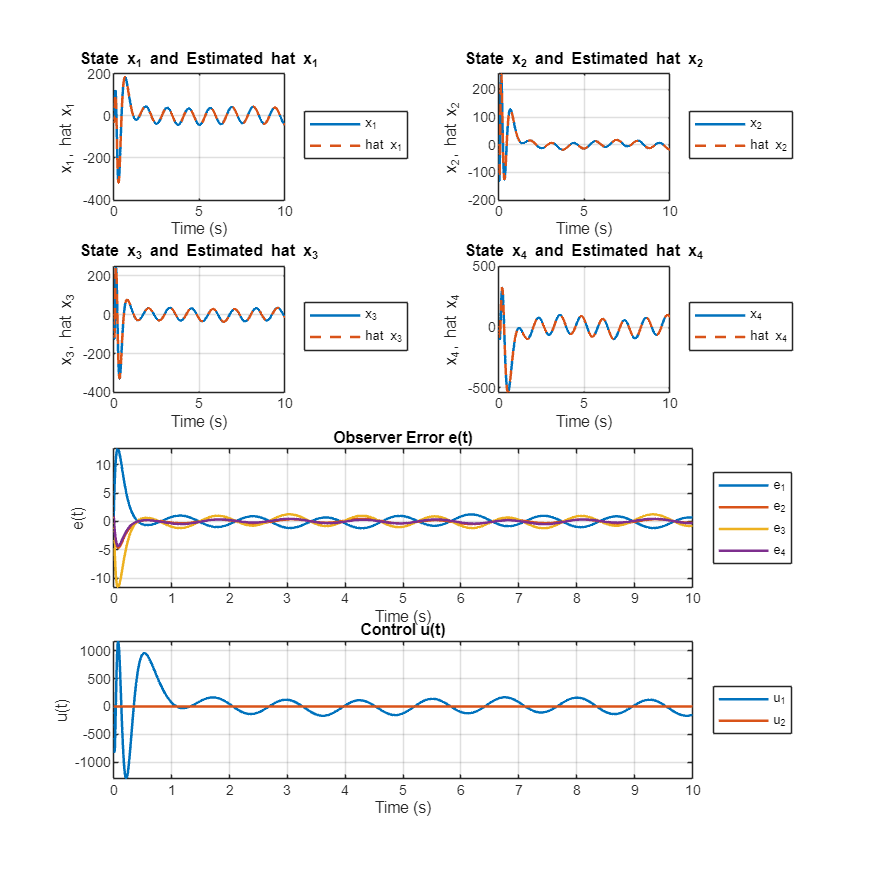

x0 = [1; 1; 1; 1];
x0_hat = zeros(4, 1);
simsys3(A, B, C, D, -K, L, x0, x0_hat, 10)